# 1. Messung K_Ventil

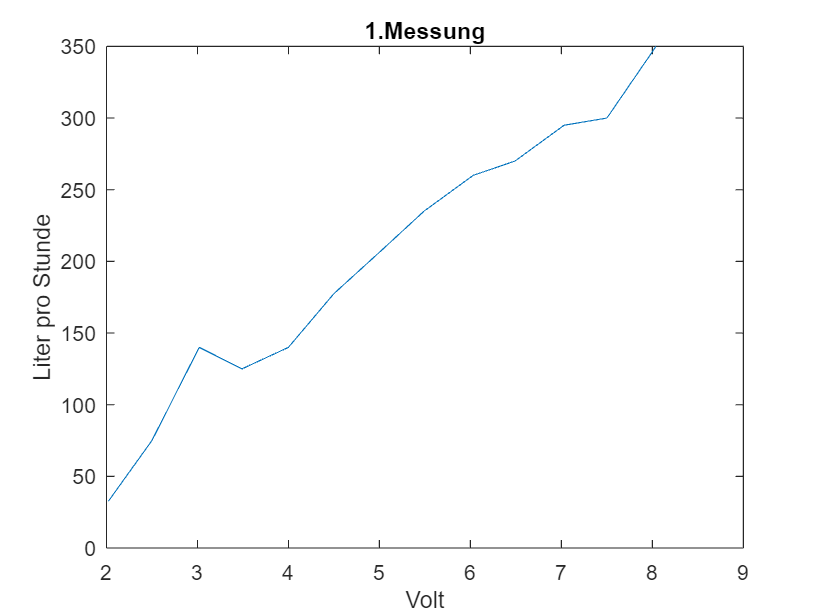

% s= Spannung 
% v= Volumenstrom

s1=[2.02 2.5 3.02 3.49 4 4.5 5.02 5.49 6.03 6.49 7.03 7.50 8.04]; %Einheit mVolt
v1= [32.5 75 140 125 140 177.5 207.5 235 260 270 295 300 350]; %Liter pro Stunde
matrix1=[s1' v1'];
plot(s1,v1)
xlabel('Volt')
ylabel('Liter pro Stunde')
title('1.Messung')

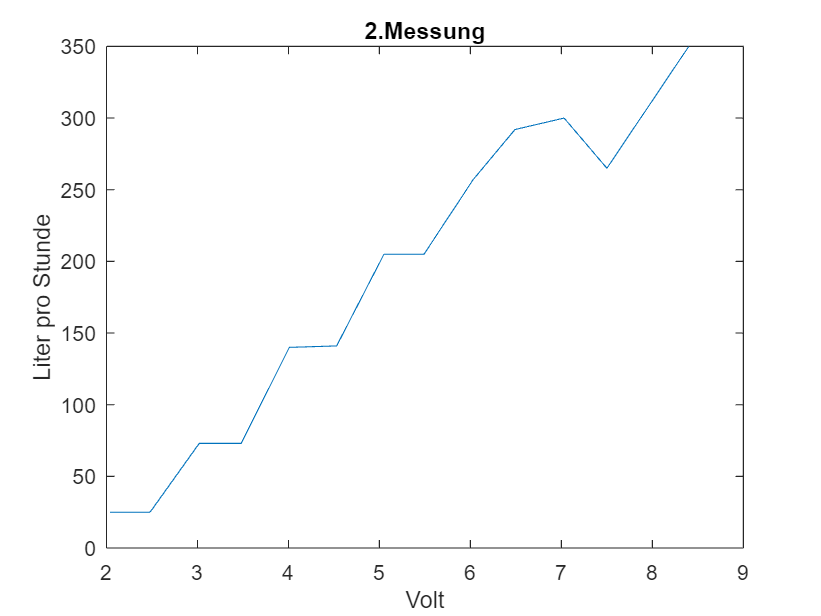




s2=[2.04 2.48 3.02 3.48 4.01 4.53 5.05 5.49 6.03 6.49 7.03 7.5 8.40]; %Einheit Volt
v2=[25 25 73 73 140 141 205 205 257 292 300 265 350]; %Liter pro Stunde
matrix2=[s2' v2'];
plot(s2,v2)
xlabel('Volt')
ylabel('Liter pro Stunde')
title('2.Messung')

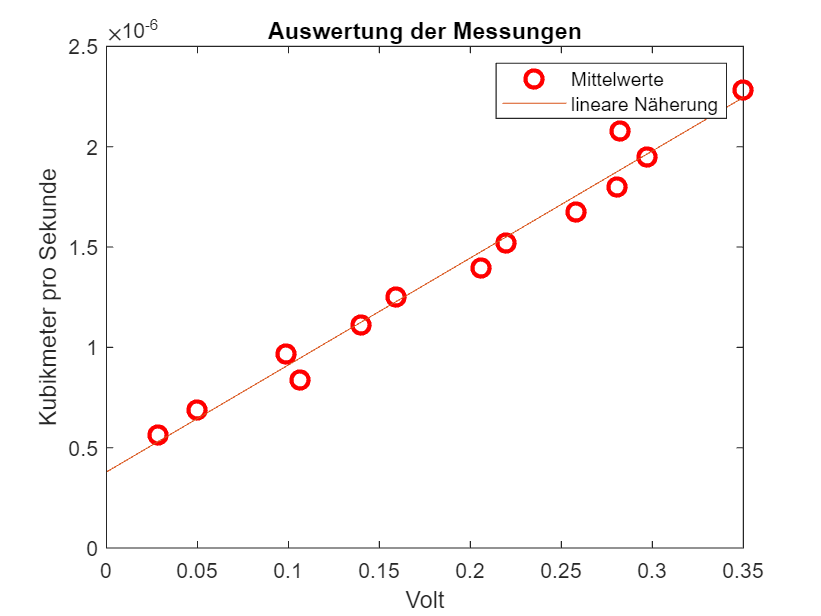



%Mittelwert
s = (s1+s2)/2/60/60/1000; % in Kubikmeter/Sekunde
v = (v1+v2)/2/1000; %in Volt
plot(v,s,'ro', 'MarkerSize', 8, 'LineWidth', 2)
xlabel('Volt')
ylabel('Kubikmeter pro Sekunde')
title('Auswertung der Messungen')

 hold on

% Lineare Näherung
pV = polyfit(v, s, 1);
K_Ventil = pV(1);
K_Ventil_Offset = pV(2);
v_linear = linspace(0,v(end),30);
s_linear = polyval(pV,v_linear);
plot(v_linear,s_linear)
legend('Mittelwerte', 'lineare Näherung')